filePath = fullfile('..','data', '24-02-15-16-46-40-112_5_500Nm__200_rpm.tdms')

%tdmsconvert(filePath, 'converted_data')

convertedPath = fullfile('.', 'converted_data', '24-02-15-16-46-40-112_5_500Nm__200_rpm.tdms')

convertedPath = '.\converted_data\24-02-15-16-46-40-112_5_500Nm__200_rpm.tdms'

data = tdmsread(convertedPath)

data = 1×1 cell array
    {4500000×6 table}


disp(data)

    {4500000×6 table}



% Assuming the large data is stored in a cell array and the first cell contains the table
largeTable = data{1};

% Display the size of the table
tableSize = size(largeTable);
disp(['Table size: ', num2str(tableSize(1)), ' rows by ', num2str(tableSize(2)), ' columns']);

Table size: 4500000 rows by 6 columns



% Display the variable names
disp('Variable names:');

Variable names:


disp(largeTable.Properties.VariableNames);

    {'Time'}    {'Dev1/ai0'}    {'Dev1/ai1'}    {'Dev1/ai2'}    {'Dev1/ai3'}    {'Dev1/ai4'}




% Display the first few rows of the table (e.g., first 10 rows)
disp('First 10 rows of the table:');

First 10 rows of the table:


disp(largeTable(1:10, :));

                Time                 Dev1/ai0      Dev1/ai1     Dev1/ai2      Dev1/ai3     Dev1/ai4 
    _____________________________    _________    __________    _________    __________    _________

    2024-02-15 16:46:40.633938399    0.0073242     0.0036621    0.0073242    -0.0024414    0.0024414
    2024-02-15 16:46:40.633948399    0.0073242     0.0036621    0.0061035    -0.0012207    0.0036621
    2024-02-15 16:46:40.633958399    0.0085449     0.0048828    0.0073242    -0.0036621    0.0048828
    2024-02-15 16:46:40.633968399    0.0061035     0.0048828    0.0048828    -0.0024414    0.0036621
    2024-02-15 16:46:40.633978399    0.0048828     0.0073242    0.0048828    -0.0036621    0.0024414
    2024-02-15 16:46:40.633988399    0.0061035     0.0036621    0.0073242    -0.0012207 

% Assuming 'data' is a cell array containing the TDMS data structures
% Access the first structure in the cell array
dataStruct = data{1};

% List all groups
groups = fieldnames(dataStruct);
disp('Groups:');

Groups:


disp(groups);

    {'Time'      }
    {'Dev1/ai0'  }
    {'Dev1/ai1'  }
    {'Dev1/ai2'  }
    {'Dev1/ai3'  }
    {'Dev1/ai4'  }
    {'Properties'}
    {'Row'       }
    {'Variables' }




% Access a specific group (e.g., the first group)
group = groups{1}; % Replace with the specific group name if necessary
disp(['Accessing group: ', group]);

Accessing group: Time



% List all channels in the specific group
channels = fieldnames(dataStruct.(group));
disp('Channels:');

Channels:


disp(channels);

    {'Format'  }
    {'TimeZone'}
    {'Year'    }
    {'Month'   }
    {'Day'     }
    {'Hour'    }
    {'Minute'  }
    {'Second'  }



% Access a specific channel (e.g., the first channel)
channel = channels{1}; % Replace with the specific channel name if necessary
disp(['Accessing channel: ', channel]);

Accessing channel: Format


% Inspect the structure of the specified channel
channelDataStruct = dataStruct.(group).(channel);
disp('Channel data structure:');

Channel data structure:


disp(channelDataStruct);

uuuu-MM-dd HH:mm:ss.SSSSSSSSS


% Assuming 'data' is a cell array containing a table
% Access the first table in the cell array
dataTable = data{1};

% Display the size of the table
disp('Table size:');

Table size:


disp(size(dataTable));

     4500000           6




% Display the first few rows of the table to understand its structure
disp('First few rows of the table:');

First few rows of the table:


disp(head(dataTable));

                Time                 Dev1/ai0     Dev1/ai1     Dev1/ai2      Dev1/ai3     Dev1/ai4 
    _____________________________    _________    _________    _________    __________    _________

    2024-02-15 16:46:40.633938399    0.0073242    0.0036621    0.0073242    -0.0024414    0.0024414
    2024-02-15 16:46:40.633948399    0.0073242    0.0036621    0.0061035    -0.0012207    0.0036621
    2024-02-15 16:46:40.633958399    0.0085449    0.0048828    0.0073242    -0.0036621    0.0048828
    2024-02-15 16:46:40.633968399    0.0061035    0.0048828    0.0048828    -0.0024414    0.0036621
    2024-02-15 16:46:40.633978399    0.0048828    0.0073242    0.0048828    -0.0036621    0.0024414
    2024-02-15 16:46:40.633988399    0.0061035    0.0036621    0.0073242    -0.0012207    0.002


% Display the variable names (column names) of the table
disp('Variable names in the table:');

Variable names in the table:


disp(dataTable.Properties.VariableNames);

    {'Time'}    {'Dev1/ai0'}    {'Dev1/ai1'}    {'Dev1/ai2'}    {'Dev1/ai3'}    {'Dev1/ai4'}




% Access a specific column (e.g., the first column)
% You can use curly braces to extract data as an array
columnData = dataTable{:, 1};  % Replace 1 with the desired column index or name

% Display basic information about the column data
disp(['Data Length: ', num2str(length(columnData))]);

Data Length: 4500000


writetable(dataTable, '500Nm_200rmp')

% Assuming 'data' is a cell array containing the TDMS data table
% Access the first table in the cell array
dataTable = data{1};

% Display the first few rows of the table to confirm its structure
disp('First few rows of the table:');

First few rows of the table:


disp(head(dataTable));

                Time                 Dev1/ai0     Dev1/ai1     Dev1/ai2      Dev1/ai3     Dev1/ai4 
    _____________________________    _________    _________    _________    __________    _________

    2024-02-15 16:46:40.633938399    0.0073242    0.0036621    0.0073242    -0.0024414    0.0024414
    2024-02-15 16:46:40.633948399    0.0073242    0.0036621    0.0061035    -0.0012207    0.0036621
    2024-02-15 16:46:40.633958399    0.0085449    0.0048828    0.0073242    -0.0036621    0.0048828
    2024-02-15 16:46:40.633968399    0.0061035    0.0048828    0.0048828    -0.0024414    0.0036621
    2024-02-15 16:46:40.633978399    0.0048828    0.0073242    0.0048828    -0.0036621    0.0024414
    2024-02-15 16:46:40.633988399    0.0061035    0.0036621    0.0073242    -0.0012207    0.002

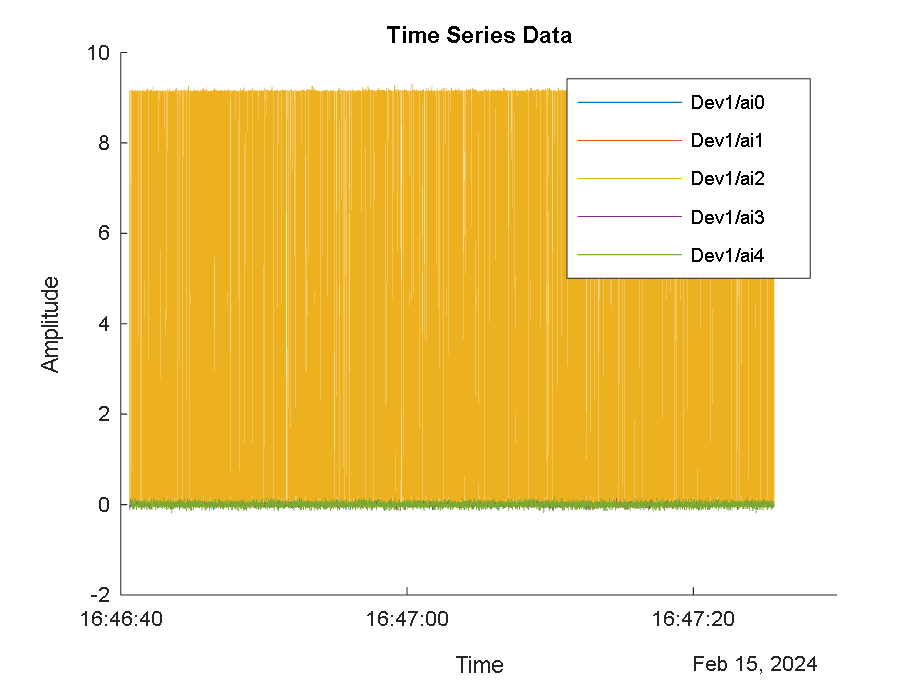


% Convert the Time column to a datetime array
dataTable.Time = datetime(dataTable.Time, 'InputFormat', 'yyyy-MM-dd HH:mm:ss.SSSSSSSSS');

% Plot the data for each channel
figure;
hold on; % Allows multiple plots on the same figure

% Plot each channel against time
for i = 2:width(dataTable)
    plot(dataTable.Time, dataTable{:, i}, 'DisplayName', dataTable.Properties.VariableNames{i});
end

% Add title and labels
title('Time Series Data');
xlabel('Time');
ylabel('Amplitude');

% Add a legend
legend show;

% Display the figure
hold off;

% Assuming 'data' is a cell array containing the TDMS data table
% Access the first table in the cell array
dataTable = data{1};

% Display the first few rows of the table to confirm its structure
disp('First few rows of the table:');

First few rows of the table:


disp(head(dataTable));

                Time                 Dev1/ai0     Dev1/ai1     Dev1/ai2      Dev1/ai3     Dev1/ai4 
    _____________________________    _________    _________    _________    __________    _________

    2024-02-15 16:46:40.633938399    0.0073242    0.0036621    0.0073242    -0.0024414    0.0024414
    2024-02-15 16:46:40.633948399    0.0073242    0.0036621    0.0061035    -0.0012207    0.0036621
    2024-02-15 16:46:40.633958399    0.0085449    0.0048828    0.0073242    -0.0036621    0.0048828
    2024-02-15 16:46:40.633968399    0.0061035    0.0048828    0.0048828    -0.0024414    0.0036621
    2024-02-15 16:46:40.633978399    0.0048828    0.0073242    0.0048828    -0.0036621    0.0024414
    2024-02-15 16:46:40.633988399    0.0061035    0.0036621    0.0073242    -0.0012207    0.002


% Convert the Time column to a datetime array
dataTable.Time = datetime(dataTable.Time, 'InputFormat', 'yyyy-MM-dd HH:mm:ss.SSSSSSSSS');

% Initialize arrays to store statistics
numChannels = width(dataTable) - 1;
means = zeros(1, numChannels);
rmsValues = zeros(1, numChannels);
variances = zeros(1, numChannels);
peakToPeaks = zeros(1, numChannels);
kurtoses = zeros(1, numChannels);
skewnesses = zeros(1, numChannels);

% Calculate statistics for each channel
for i = 2:width(dataTable)
    channelData = dataTable{:, i};
    means(i-1) = mean(channelData);
    rmsValues(i-1) = rms(channelData);
    variances(i-1) = var(channelData);
    peakToPeaks(i-1) = peak2peak(channelData);
    kurtoses(i-1) = kurtosis(channelData);
    skewnesses(i-1) = skewness(channelData);
end

% Display statistics
for i = 2:width(dataTable)
    channelName = dataTable.Properties.VariableNames{i};
    fprintf('Statistics for %s:\n', channelName);
    fprintf('  Mean: %f\n', means(i-1));
    fprintf('  RMS: %f\n', rmsValues(i-1));
    fprintf('  Variance: %f\n', variances(i-1));
    fprintf('  Peak-to-Peak: %f\n', peakToPeaks(i-1));
    fprintf('  Kurtosis: %f\n', kurtoses(i-1));
    fprintf('  Skewness: %f\n', skewnesses(i-1));
end

Statistics for Dev1/ai0:


  Mean: 0.003012


  RMS: 0.008915


  Variance: 0.000070


  Peak-to-Peak: 0.311279


  Kurtosis: 4.828284


  Skewness: 0.035134


Statistics for Dev1/ai1:


  Mean: 0.002760


  RMS: 0.009191


  Variance: 0.000077


  Peak-to-Peak: 0.316162


  Kurtosis: 7.345830


  Skewness: 0.358140


Statistics for Dev1/ai2:


  Mean: 1.603415


  RMS: 3.826273


  Variance: 12.069426


  Peak-to-Peak: 9.378662


  Kurtosis: 3.912294


  Skewness: 1.706481


Statistics for Dev1/ai3:


  Mean: -0.002018


  RMS: 0.003457


  Variance: 0.000008


  Peak-to-Peak: 0.325928


  Kurtosis: 413.882061


  Skewness: -0.261232


Statistics for Dev1/ai4:


  Mean: 0.002435


  RMS: 0.003872


  Variance: 0.000009


  Peak-to-Peak: 0.355225


  Kurtosis: 437.185962


  Skewness: -0.298211


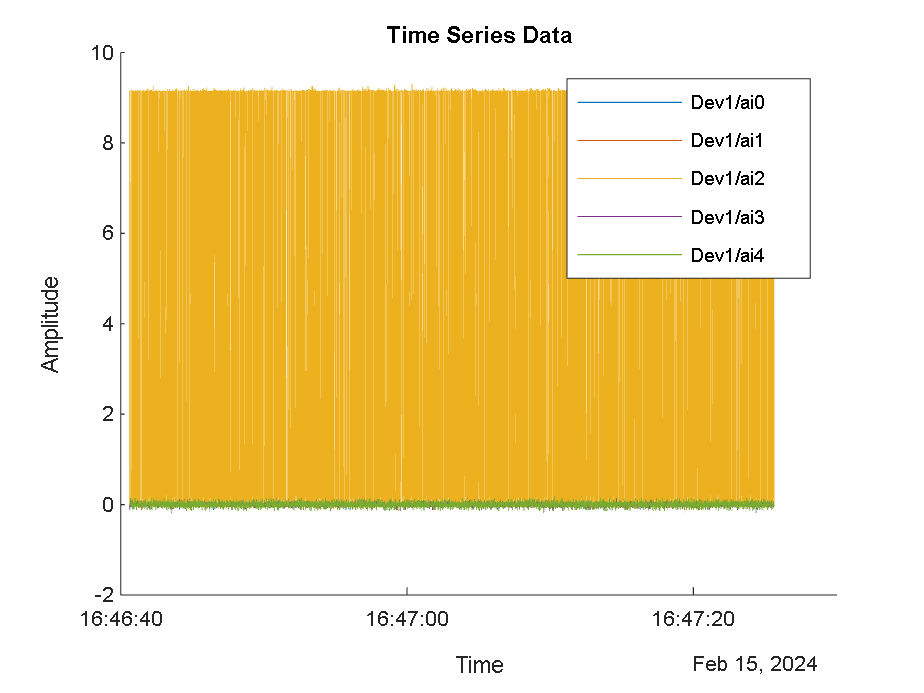


% Plot the data for each channel
figure;
hold on; % Allows multiple plots on the same figure

% Plot each channel against time
for i = 2:width(dataTable)
    plot(dataTable.Time, dataTable{:, i}, 'DisplayName', dataTable.Properties.VariableNames{i});
end

% Add title and labels
title('Time Series Data');
xlabel('Time');
ylabel('Amplitude');

% Add a legend
legend show;

% Display the figure
hold off;

% Assuming 'data' is a cell array containing the TDMS data table
% Access the first table in the cell array
dataTable = data{1};

% Display the first few rows of the table to confirm its structure
disp('First few rows of the table:');

First few rows of the table:


disp(head(dataTable));

                Time                 Dev1/ai0     Dev1/ai1     Dev1/ai2      Dev1/ai3     Dev1/ai4 
    _____________________________    _________    _________    _________    __________    _________

    2024-02-15 16:46:40.633938399    0.0073242    0.0036621    0.0073242    -0.0024414    0.0024414
    2024-02-15 16:46:40.633948399    0.0073242    0.0036621    0.0061035    -0.0012207    0.0036621
    2024-02-15 16:46:40.633958399    0.0085449    0.0048828    0.0073242    -0.0036621    0.0048828
    2024-02-15 16:46:40.633968399    0.0061035    0.0048828    0.0048828    -0.0024414    0.0036621
    2024-02-15 16:46:40.633978399    0.0048828    0.0073242    0.0048828    -0.0036621    0.0024414
    2024-02-15 16:46:40.633988399    0.0061035    0.0036621    0.0073242    -0.0012207    0.002

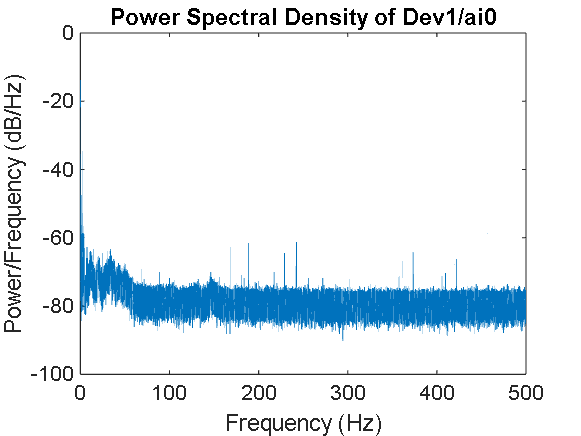

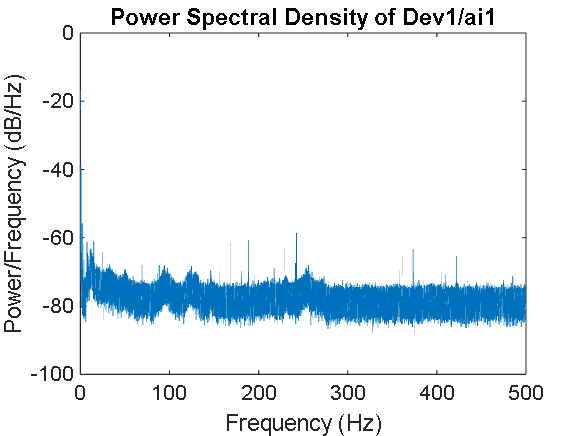

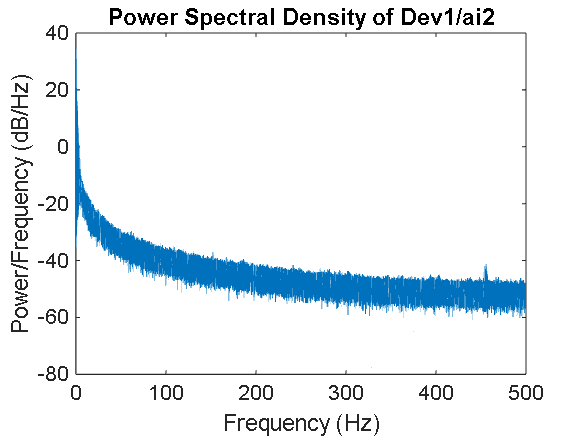

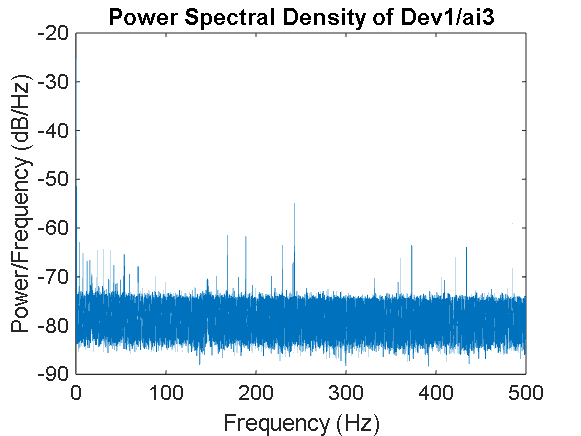

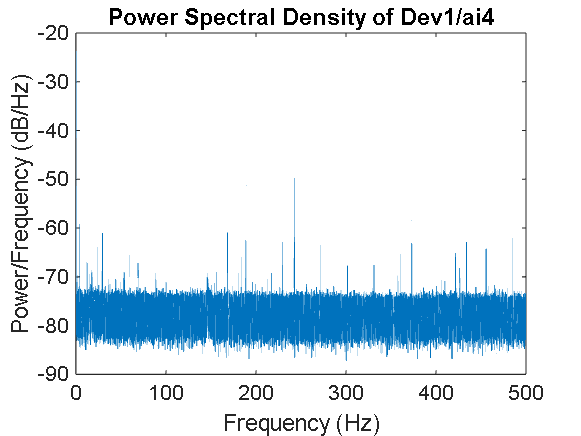


% Convert the Time column to a datetime array
dataTable.Time = datetime(dataTable.Time, 'InputFormat', 'yyyy-MM-dd HH:mm:ss.SSSSSSSSS');

% Frequency domain analysis parameters
Fs = 1000; % Sampling frequency (Hz), adjust this value based on your data
N = length(dataTable.Time); % Number of samples
T = 1 / Fs; % Sampling period

% Initialize arrays to store frequency domain features
numChannels = width(dataTable) - 1;
peakFrequencies = zeros(1, numChannels);
bandPowers = zeros(1, numChannels);
spectralCentroids = zeros(1, numChannels);

% Frequency domain analysis for each channel
for i = 2:width(dataTable)
    channelData = dataTable{:, i};
    
    % Compute the Fourier Transform
    Y = fft(channelData);
    P2 = abs(Y / N);
    P1 = P2(1:N/2+1);
    P1(2:end-1) = 2 * P1(2:end-1);
    
    % Frequency vector
    f = Fs * (0:(N/2)) / N;
    
    % Estimate the Power Spectral Density (PSD) using Welch's method
    [pxx, f_psd] = pwelch(channelData, [], [], [], Fs);
    
    % Find peak frequencies
    [~, locs] = findpeaks(pxx, 'SortStr', 'descend');
    peakFrequencies(i-1) = f_psd(locs(1));
    
    % Compute band power (e.g., in the band 0-50 Hz)
    band = (f_psd >= 0 & f_psd <= 50);
    bandPowers(i-1) = bandpower(pxx, f_psd, 'psd', band);
    
    % Compute spectral centroid
    spectralCentroids(i-1) = sum(f_psd .* pxx) / sum(pxx);
    
    % Plot the Power Spectral Density
    figure;
    plot(f_psd, 10*log10(pxx));
    title(['Power Spectral Density of ', dataTable.Properties.VariableNames{i}]);
    xlabel('Frequency (Hz)');
    ylabel('Power/Frequency (dB/Hz)');
end


% Display frequency domain features
for i = 2:width(dataTable)
    channelName = dataTable.Properties.VariableNames{i};
    fprintf('Frequency Domain Features for %s:\n', channelName);
    fprintf('  Peak Frequency: %f Hz\n', peakFrequencies(i-1));
    fprintf('  Band Power (0-50 Hz): %f\n', bandPowers(i-1));
    fprintf('  Spectral Centroid: %f Hz\n', spectralCentroids(i-1));
end

Frequency Domain Features for Dev1/ai0:


  Peak Frequency: 0.033379 Hz


  Band Power (0-50 Hz): 0.000079


  Spectral Centroid: 20.840616 Hz


Frequency Domain Features for Dev1/ai1:


  Peak Frequency: 0.033379 Hz


  Band Power (0-50 Hz): 0.000081


  Spectral Centroid: 26.978042 Hz


Frequency Domain Features for Dev1/ai2:


  Peak Frequency: 0.134468 Hz


  Band Power (0-50 Hz): 14.622897


  Spectral Centroid: 0.692251 Hz


Frequency Domain Features for Dev1/ai3:


  Peak Frequency: 0.499725 Hz


  Band Power (0-50 Hz): 0.000012


  Spectral Centroid: 158.638749 Hz


Frequency Domain Features for Dev1/ai4:


  Peak Frequency: 242.617607 Hz


  Band Power (0-50 Hz): 0.000015


  Spectral Centroid: 146.205296 Hz


% Assuming 'data' is a cell array containing the TDMS data table
% Access the first table in the cell array
dataTable = data{1};

% Display the first few rows of the table to confirm its structure
disp('First few rows of the table:');

First few rows of the table:


disp(head(dataTable));

                Time                 Dev1/ai0     Dev1/ai1     Dev1/ai2      Dev1/ai3     Dev1/ai4 
    _____________________________    _________    _________    _________    __________    _________

    2024-02-15 16:46:40.633938399    0.0073242    0.0036621    0.0073242    -0.0024414    0.0024414
    2024-02-15 16:46:40.633948399    0.0073242    0.0036621    0.0061035    -0.0012207    0.0036621
    2024-02-15 16:46:40.633958399    0.0085449    0.0048828    0.0073242    -0.0036621    0.0048828
    2024-02-15 16:46:40.633968399    0.0061035    0.0048828    0.0048828    -0.0024414    0.0036621
    2024-02-15 16:46:40.633978399    0.0048828    0.0073242    0.0048828    -0.0036621    0.0024414
    2024-02-15 16:46:40.633988399    0.0061035    0.0036621    0.0073242    -0.0012207    0.002

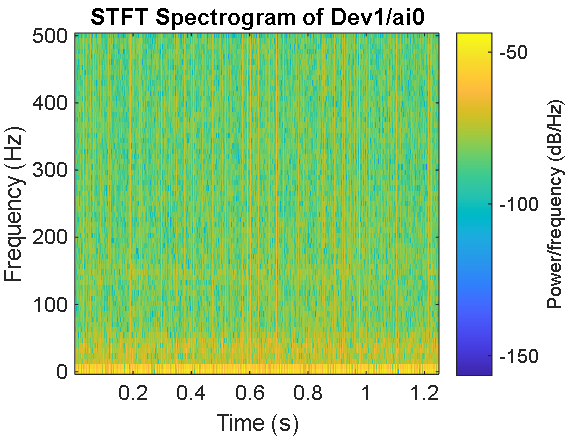

cwt requires Wavelet Toolbox.


% Convert the Time column to a datetime array
dataTable.Time = datetime(dataTable.Time, 'InputFormat', 'yyyy-MM-dd HH:mm:ss.SSSSSSSSS');

% Frequency domain analysis parameters
Fs = 1000; % Sampling frequency (Hz), adjust this value based on your data
N = length(dataTable.Time); % Number of samples
T = 1 / Fs; % Sampling period

% Initialize arrays to store features
numChannels = width(dataTable) - 1;
stftFeatures = cell(1, numChannels);
waveletCoefficients = cell(1, numChannels);

% Time-frequency analysis for each channel
for i = 2:width(dataTable)
    channelData = dataTable{:, i};
    
    % Short-Time Fourier Transform (STFT)
    [s, f, t] = stft(channelData, Fs);
    
    % Visualize STFT with a spectrogram
    figure;
    spectrogram(channelData, 128, 120, 128, Fs, 'yaxis');
    title(['STFT Spectrogram of ', dataTable.Properties.VariableNames{i}]);
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    
    % Extract STFT features (magnitude and phase)
    stftFeatures{i-1}.magnitude = abs(s);
    stftFeatures{i-1}.phase = angle(s);
    
    % Continuous Wavelet Transform (CWT)
    [wt, f_wt] = cwt(channelData, Fs);
    
    % Visualize CWT
    figure;
    surface(t, f_wt, abs(wt));
    axis tight;
    shading flat;
    title(['CWT Spectrogram of ', dataTable.Properties.VariableNames{i}]);
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    
    % Extract wavelet coefficients
    waveletCoefficients{i-1} = wt;
end


% Display feature extraction completion
disp('STFT features and Wavelet coefficients extracted for each channel.');
